# Análisis de fórmulas de derivación numérica

Integrantes:

- Bernardo Padilla Fischer 182748

- Rodrigo Plauchú Rodríguez 182671

- Victor Hugo Castillejos Corzo 182344

En este documento se analizará el error que se obtiene con cada método de derivación numérica. Se explorarán las aproximaciones centradas, hacia adelante y hacia atrás de la primera y segunda derivada. Por otro lado, se verá gráficamente cuál es la fórmula que aproxima mejor el valor de la derivada. Las gráficas van a estar representadas en escala log-log.

**¿De dónde surgen estas fórmulas?**

El método de diferencias finitas viene del teorema de Taylor, ya que si se expande una serie de Taylor se puede truncar un polinomio de Taylor con la funcion original. Esto nos dará una oproximación de la derivada de la función.

La serie de Taylor predice el valor de una función en un punto en términos del valor de la función y sus derivadas. Matemáticamente:


$$f\left(x_0 \right)=f\left(x_0 \right)+\frac{x-x_0 }{1!}f^{\prime } \left(x_0 \right)+\frac{{\left(x-x_0 \right)}^2 }{2!}f^{\prime \prime } \left(x_0 \right)+\ldotp \ldotp \ldotp +\frac{{\left(x-x_0 \right)}^n }{n!}f^{\left(n\right)} \left(x_0 \right)+R_n$$


#### Aproximaciones de la función polinomial $f\left(x\right)=-0\ldotp 7x^4 -0\ldotp 5x^3 -0\ldotp 9x^2 -1\ldotp 25x+7\ldotp 2$ con `x = 0.5`

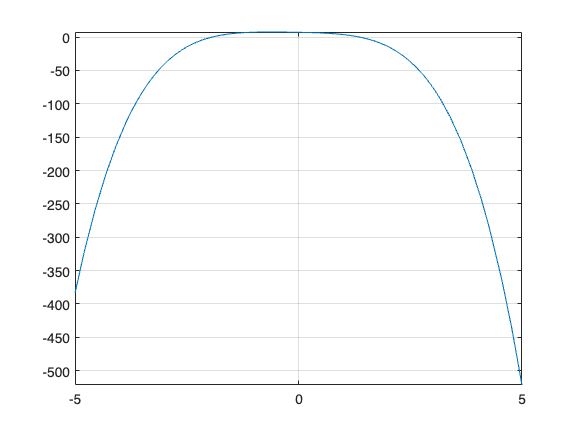

format long;
f = @(x) -0.7 * x.^4 - 0.5 * x.^3 - 0.9 * x.^2 - 1.25 * x + 7.2;
x = 0.5;
fplot(f)
grid on;

df = matlabFunction(diff(sym(f)));
dfx = df(x)

dfx =   -2.875000000000000


El valor real de la primera derivada de la función en el punto` x `es `-2.8750`. Este es el valor que se desea aproximar.

**Aproximaciones hacia adelante de primer y segundo orden:**

## Resultados de cada uno de los métodos de aproximación de derivación numérica

#### Aproximación de la primera derivada hacia adelante con $O\left(h\right)$

Primera derivada: Aproximación hacia adelante O(h)
	 h 	     aproximación 	 	 error
  1.0000000000 	 -8.17500000000000 	  5.3000000000000
  0.1000000000 	 -3.16470000000001 	  0.2897000000000
  0.0100000000 	 -2.90219070000006 	  0.0271907000001
  0.0010000000 	 -2.87770190070002 	  0.0027019007000
  0.0001000000 	 -2.87527001900045 	  0.0002700190005
  0.0000100000 	 -2.87502700020426 	  0.0000270002043
  0.0000010000 	 -2.87500269990915 	  0.0000026999091
  0.0000001000 	 -2.87500027340570 	  0.0000002734057
  0.0000000100 	 -2.87500006024288 	  0.0000000602429
  0.0000000010 	 -2.87499979378936 	 -0.0000002062106
  0.0000000001 	 -2.87499801743252 	 -0.0000019825675


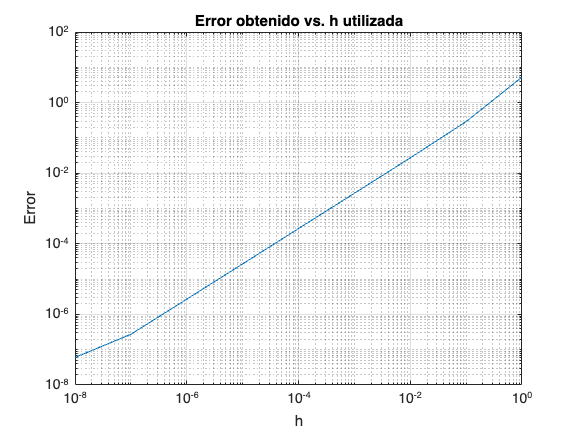

dfForward1(f,x)

#### Aproximación de la primera derivada hacia adelante con $O\left(h^2 \right)$

Primera derivada: Aproximación hacia adelante O(h^2)
	 h 	     aproximación 	 	 error
  1.0000000000 	 5.12500000000000 	 -8.0000000000000
  0.1000000000 	 -2.83280000000001 	 -0.0422000000000
  0.0100000000 	 -2.87461580000024 	 -0.0003841999998
  0.0010000000 	 -2.87499619579989 	 -0.0000038042001
  0.0001000000 	 -2.87499996201035 	 -0.0000000379897
  0.0000100000 	 -2.87499999966911 	 -0.0000000003309
  0.0000010000 	 -2.87499999984675 	 -0.0000000001532
  0.0000001000 	 -2.87500000695218 	  0.0000000069522
  0.0000000100 	 -2.87500014906072 	  0.0000001490607
  0.0000000010 	 -2.87499979378936 	 -0.0000002062106
  0.0000000001 	 -2.87499801743252 	 -0.0000019825675


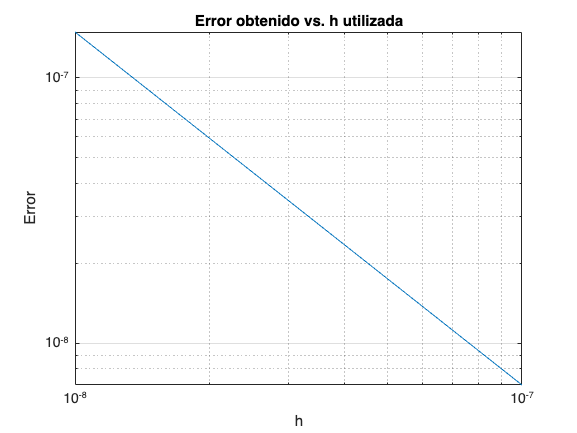

dfForward2(f,x)

#### Aproximación de la primera derivada centrada con $O\left(h^2 \right)$

Primera derivada: Aproximación centrada O(h^2)
	 h 	     aproximación 	 	 error
  1.0000000000 	 -4.77500000000000 	  1.9000000000000
  0.1000000000 	 -2.89400000000000 	  0.0190000000000
  0.0100000000 	 -2.87519000000001 	  0.0001900000000
  0.0010000000 	 -2.87500190000012 	  0.0000019000001
  0.0001000000 	 -2.87500001900032 	  0.0000000190003
  0.0000100000 	 -2.87500000020202 	  0.0000000002020
  0.0000010000 	 -2.87499999984675 	 -0.0000000001532
  0.0000001000 	 -2.87500000251129 	  0.0000000025113
  0.0000000100 	 -2.87500001583396 	  0.0000000158340
  0.0000000010 	 -2.87499979378936 	 -0.0000002062106
  0.0000000001 	 -2.87499801743252 	 -0.0000019825675


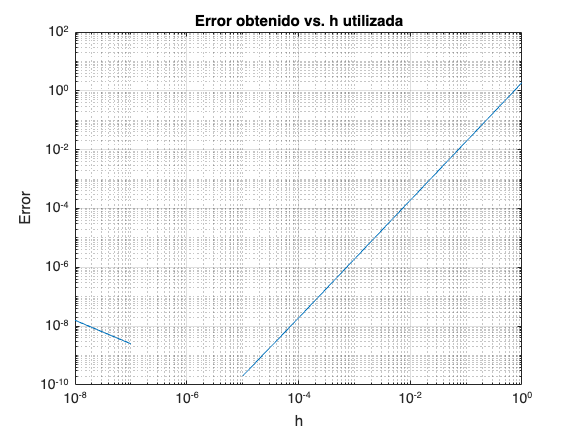

dfCentral(f,x)

#### Aproximación de la primera derivada hacia atrás con $O\left(h\right)$

Primera derivada: Aproximación hacia atrás O(h)
	 h 	     aproximación 	 	 error
  1.0000000000 	 -1.37500000000000 	 -1.5000000000000
  0.1000000000 	 -2.62330000000000 	 -0.2517000000000
  0.0100000000 	 -2.84818929999995 	 -0.0268107000001
  0.0010000000 	 -2.87230189930021 	 -0.0026981006998
  0.0001000000 	 -2.87473001900018 	 -0.0002699809998
  0.0000100000 	 -2.87497300019979 	 -0.0000269998002
  0.0000010000 	 -2.87499729978435 	 -0.0000027002156
  0.0000001000 	 -2.87499973161687 	 -0.0000002683831
  0.0000000100 	 -2.87499997142504 	 -0.0000000285750
  0.0000000010 	 -2.87499979378936 	 -0.0000002062106
  0.0000000001 	 -2.87499801743252 	 -0.0000019825675


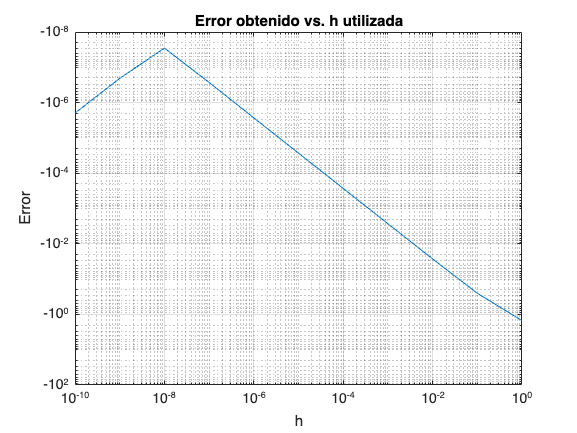

dfBackward1(f,x)

#### Aproximación de la primera derivada hacia atrás con $O\left(h^2 \right)$

dfBackward2(f,x)

Primera derivada: Aproximación hacia atrás O(h^2)
	 h 	     aproximación 	 	 error
  1.0000000000 	 -3.27500000000000 	  0.4000000000000
  0.1000000000 	 -2.84119999999998 	 -0.0338000000000
  0.0100000000 	 -2.87462419999982 	 -0.0003758000002
  0.0010000000 	 -2.87499620419940 	 -0.0000037958006
  0.0001000000 	 -2.87499996199703 	 -0.0000000380030
  0.0000100000 	 -2.87499999958030 	 -0.0000000004197
  0.0000010000 	 -2.87499999895857 	 -0.0000000010414
  0.0000001000 	 -2.87499999362950 	 -0.0000000063705
  0.0000000100 	 -2.87499992701612 	 -0.0000000729839
  0.0000000010 	 -2.87499890561094 	 -0.0000010943891
  0.0000000001 	 -2.87498913564832 	 -0.0000108643517


**Gráfica con los errores de los métodos para comparar**

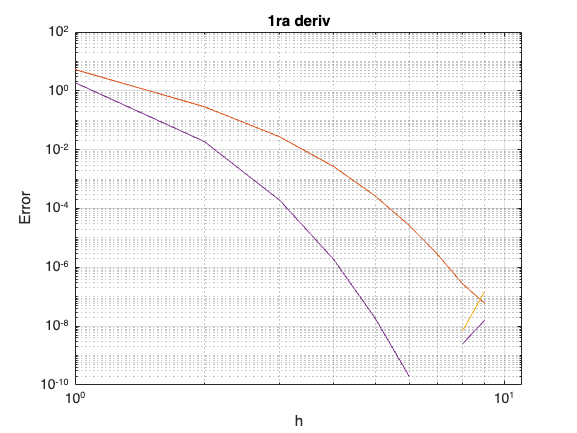

grafTodas1era(f, x)

#### Segunda derivada

ddf = matlabFunction(diff(diff(sym(f))));
ddfx = ddf(x)

ddfx = -5.4000

El valor real de la segunda derivada de la función en el punto` x `es `-5.400`. Este es el valor que se desea aproximar.

**Aproximaciones hacia adelante de primer y segundo orden:**

#### Aproximación de la segunda derivada hacia adelante (análogamente hacia atrás) con $O\left(h\right)$

Segunda derivada: Aproximación hacia adelante O(h)
	 h 	     aproximación 	 	 error
  1.0000000000 	 -26.60000000000000 	 21.2000000000000
  0.1000000000 	 -0.06638000000000 	  5.3336200000000
  0.0100000000 	 -0.00055149800000 	  5.3994485020000
  0.0010000000 	 -0.00000541140980 	  5.3999945885902
  0.0001000000 	 -0.00000005401140 	  5.3999999459886
  0.0000100000 	 -0.00000000054001 	  5.3999999994600
  0.0000010000 	 -0.00000000000540 	  5.3999999999946
  0.0000001000 	 -0.00000000000005 	  5.3999999999999
  0.0000000100 	 0.00000000000000 	  5.4000000000000
  0.0000000010 	 -0.00000000000000 	  5.4000000000000
  0.0000000001 	 -0.00000000000000 	  5.4000000000000


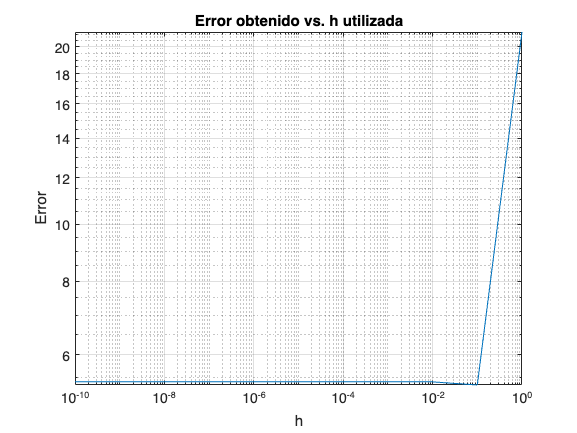

ddfForward1(f,x)

#### Aproximación de la segunda derivada hacia adelante (análogamente hacia atrás) con $O\left(h^2 \right)$

Segunda derivada: Aproximación hacia adelante O(h^2)
	 h 	     aproximación 	 	 error
  1.0000000000 	 10.00000000000001 	 15.4000000000000
  0.1000000000 	 -5.24599999999964 	  0.1540000000004
  0.0100000000 	 -5.39845999998789 	  0.0015400000121
  0.0010000000 	 -5.39998460169500 	  0.0000153983050
  0.0001000000 	 -5.40000009152664 	  0.0000000915266
  0.0000100000 	 -5.40001821036640 	  0.0000182103664
  0.0000010000 	 -5.39657207809796 	  0.0034279219020
  0.0000001000 	 -5.32907051820075 	  0.0709294817992
  0.0000000100 	 0.00000000000000 	  5.4000000000000
  0.0000000010 	 -3552.71367880050047 	 3547.3136788005004
  0.0000000001 	 0.00000000000000 	  5.4000000000000


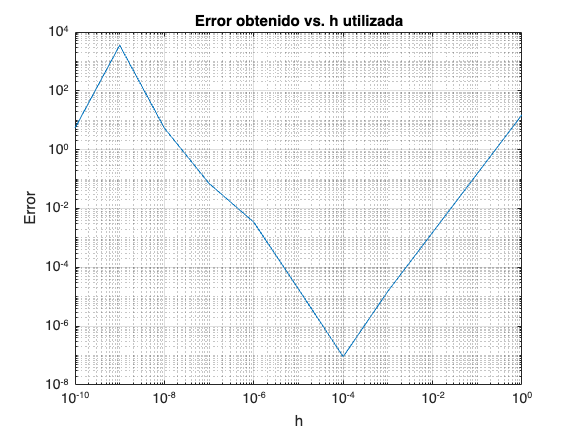

ddfForward2(f,x)

#### Aproximación de la segunda derivada centrada con $O\left(h^2 \right)$

ddfCentral(f,x)

Segunda derivada: Aproximación centrada O(h^2)
	 h 	     aproximación 	 	 error
  1.0000000000 	 -6.80000000000000 	  1.4000000000000
  0.1000000000 	 -5.41400000000012 	  0.0140000000001
  0.0100000000 	 -5.40014000001143 	  0.0001400000114
  0.0010000000 	 -5.40000139981345 	  0.0000013998134
  0.0001000000 	 -5.40000000270879 	  0.0000000027088
  0.0000100000 	 -5.40000044679800 	  0.0000004467980
  0.0000010000 	 -5.40012479177676 	  0.0001247917768
  0.0000001000 	 -5.41788836017076 	  0.0178883601708
  0.0000000100 	 -8.88178419700125 	  3.4817841970013
  0.0000000010 	 0.00000000000000 	  5.4000000000000
  0.0000000001 	 0.00000000000000 	  5.4000000000000


**Gráfica con los errores de los métodos para comparar**

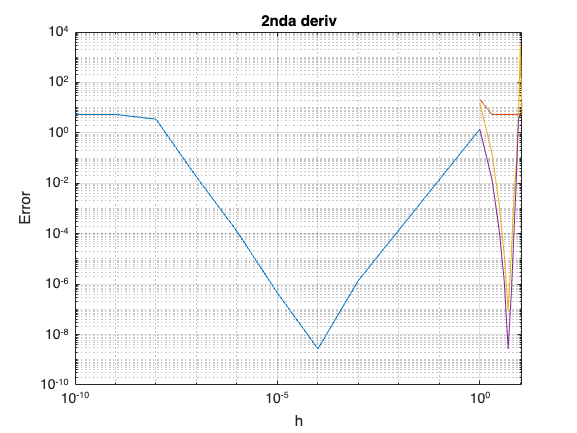

grafTodas2nda(f, x)

**Para asegurarnos que se contemplaron los casos de error probaremos las funciones con:**

- **Una función trigonométrica**

- **Una función que su primera derivada sea constante**

### Aproximaciones de la función trigonométrica $f\left(x\right)=\frac{\sin \left(x^2 \right)}{x^2 }$ con `x = 6.8`

f = @(x) sin(x.^2) ./ x.^2;
x = 6.8;

df = matlabFunction(diff(sym(f)));
dfx = df(x)

dfx = -0.1914

El valor real de la primera derivada de la función en el punto` x `es `-0.1914`. Este es el valor que se desea aproximar.

**Aproximaciones hacia adelante de primer y segundo orden:**

## Resultados de cada uno de los métodos de aproximación de derivación numérica

#### Aproximación de la primera derivada hacia adelante con $O\left(h\right)$

Primera derivada: Aproximación hacia adelante O(h)
	 h 	     aproximación 	 	 error
  1.0000000000 	 -0.03172264620255 	 -0.1597097094023
  0.1000000000 	 -0.26534559950083 	  0.0739132438960
  0.0100000000 	 -0.20585460547605 	  0.0144222498712
  0.0010000000 	 -0.19293055868323 	  0.0014982030784
  0.0001000000 	 -0.19158271540830 	  0.0001503598035
  0.0000100000 	 -0.19144739695880 	  0.0000150413540
  0.0000010000 	 -0.19143385985784 	  0.0000015042530
  0.0000001000 	 -0.19143250647863 	  0.0000001508738
  0.0000000100 	 -0.19143237654784 	  0.0000000209430
  0.0000000010 	 -0.19143237342534 	  0.0000000178205
  0.0000000001 	 -0.19143239077257 	  0.0000000351677


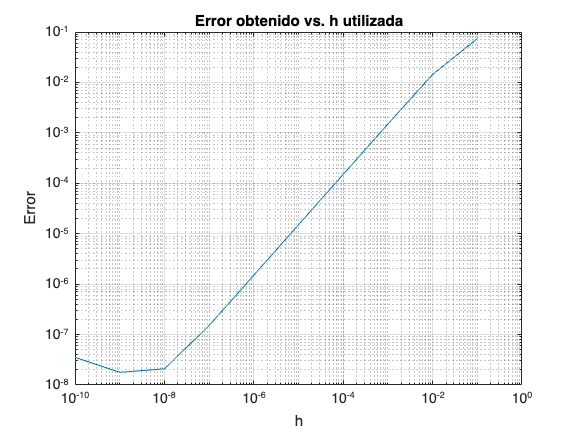

dfForward1(f,x)

#### Aproximación de la primera derivada hacia adelante con $O\left(h^2 \right)$

Primera derivada: Aproximación hacia adelante O(h^2)
	 h 	     aproximación 	 	 error
  1.0000000000 	 -0.06083808388641 	 -0.1305942717184
  0.1000000000 	 -0.34976099684609 	  0.1583286412412
  0.0100000000 	 -0.19275847165444 	  0.0013261160496
  0.0010000000 	 -0.19144443258551 	  0.0000120769807
  0.0001000000 	 -0.19143247511920 	  0.0000001195144
  0.0000100000 	 -0.19143235679558 	  0.0000000011907
  0.0000010000 	 -0.19143235570340 	  0.0000000000986
  0.0000001000 	 -0.19143235649444 	  0.0000000008896
  0.0000000100 	 -0.19143236648644 	  0.0000000108816
  0.0000000010 	 -0.19143236995589 	  0.0000000143510
  0.0000000001 	 -0.19143239077257 	  0.0000000351677


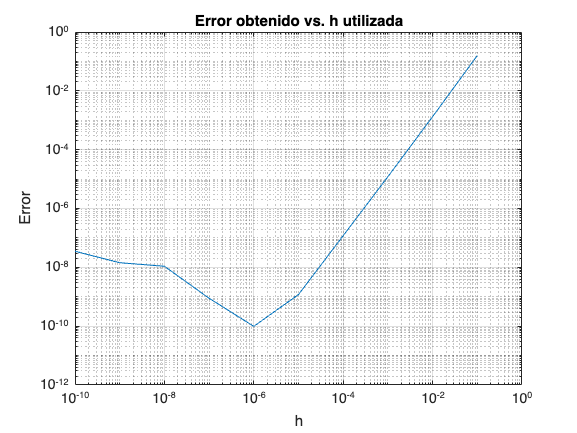

dfForward2(f,x)

#### Aproximación de la primera derivada centrada con $O\left(h^2 \right)$

Primera derivada: Aproximación centrada O(h^2)
	 h 	     aproximación 	 	 error
  1.0000000000 	 -0.01930333024841 	 -0.1721290253564
  0.1000000000 	 -0.13684462562175 	 -0.0545877299831
  0.0100000000 	 -0.19083601146215 	 -0.0005963441427
  0.0010000000 	 -0.19142638691146 	 -0.0000059686934
  0.0001000000 	 -0.19143229591713 	 -0.0000000596877
  0.0000100000 	 -0.19143235499963 	 -0.0000000006052
  0.0000010000 	 -0.19143235563575 	  0.0000000000309
  0.0000001000 	 -0.19143235595667 	  0.0000000003518
  0.0000000100 	 -0.19143235659852 	  0.0000000009937
  0.0000000010 	 -0.19143237169061 	  0.0000000160858
  0.0000000001 	 -0.19143237342534 	  0.0000000178205


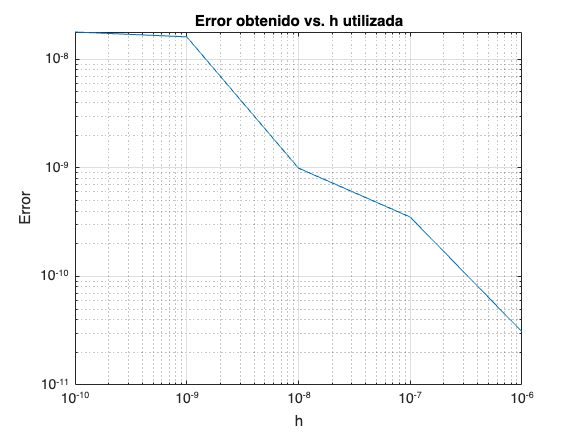

dfCentral(f,x)

#### Aproximación de la primera derivada hacia atrás con $O\left(h\right)$

Primera derivada: Aproximación hacia atrás O(h)
	 h 	     aproximación 	 	 error
  1.0000000000 	 -0.00688401429426 	 -0.1845483413106
  0.1000000000 	 -0.00834365174267 	 -0.1830887038622
  0.0100000000 	 -0.17581741744826 	 -0.0156149381566
  0.0010000000 	 -0.18992221513969 	 -0.0015101404652
  0.0001000000 	 -0.19128187642596 	 -0.0001504791789
  0.0000100000 	 -0.19141731304045 	 -0.0000150425644
  0.0000010000 	 -0.19143085141365 	 -0.0000015041912
  0.0000001000 	 -0.19143220543472 	 -0.0000001501701
  0.0000000100 	 -0.19143233664920 	 -0.0000000189556
  0.0000000010 	 -0.19143236995589 	  0.0000000143510
  0.0000000001 	 -0.19143235607810 	  0.0000000004733


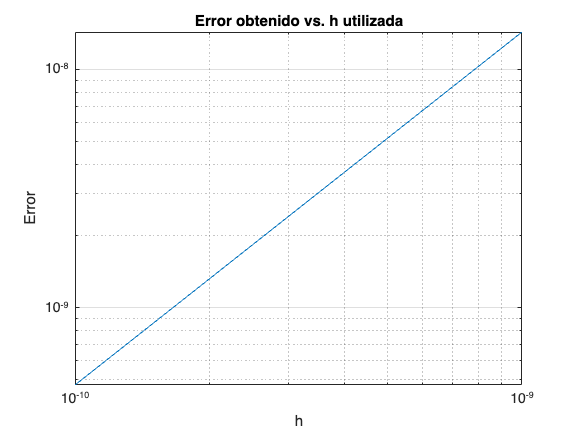

dfBackward1(f,x)

#### Aproximación de la primera derivada hacia atrás con $O\left(h^2 \right)$

dfBackward2(f,x)

Primera derivada: Aproximación hacia atrás O(h^2)
	 h 	     aproximación 	 	 error
  1.0000000000 	 -0.04094075291934 	 -0.1504916026855
  0.1000000000 	 -0.14734090255213 	 -0.0440914530527
  0.0100000000 	 -0.19247890424646 	  0.0010465486416
  0.0010000000 	 -0.19144415212449 	  0.0000117965196
  0.0001000000 	 -0.19143247483868 	  0.0000001192338
  0.0000100000 	 -0.19143235676488 	  0.0000000011600
  0.0000010000 	 -0.19143235565483 	  0.0000000000500
  0.0000001000 	 -0.19143235647709 	  0.0000000008722
  0.0000000100 	 -0.19143235191477 	 -0.0000000036901
  0.0000000010 	 -0.19143237516006 	  0.0000000195552
  0.0000000001 	 -0.19143237342534 	  0.0000000178205


**Gráfica con los errores de los métodos para comparar**

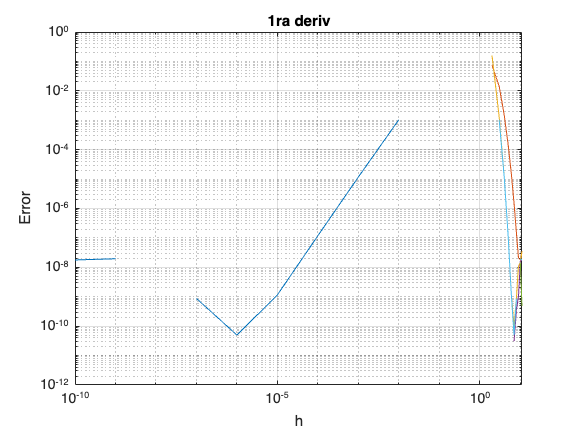

grafTodas1era(f, x)

#### Segunda derivada

ddf = matlabFunction(diff(diff(sym(f))));
ddfx = ddf(x)

ddfx = -3.0084

El valor real de la segunda derivada de la función en el punto` x `es `-3.0084`. Este es el valor que se desea aproximar.

**Aproximaciones hacia adelante de primer y segundo orden:**

#### Aproximación de la segunda derivada hacia adelante (análogamente hacia atrás) con $O\left(h\right)$

Segunda derivada: Aproximación hacia adelante O(h)
	 h 	     aproximación 	 	 error
  1.0000000000 	 0.05823087536770 	  3.0666211634350
  0.1000000000 	 0.01688307946905 	  3.0252733675364
  0.0100000000 	 -0.00026192267643 	  3.0081283653909
  0.0010000000 	 -0.00000297225220 	  3.0083873158151
  0.0001000000 	 -0.00000003004806 	  3.0083902580193
  0.0000100000 	 -0.00000000030080 	  3.0083902877665
  0.0000010000 	 -0.00000000000301 	  3.0083902880643
  0.0000001000 	 -0.00000000000003 	  3.0083902880673
  0.0000000100 	 -0.00000000000000 	  3.0083902880673
  0.0000000010 	 -0.00000000000000 	  3.0083902880673
  0.0000000001 	 0.00000000000000 	  3.0083902880673


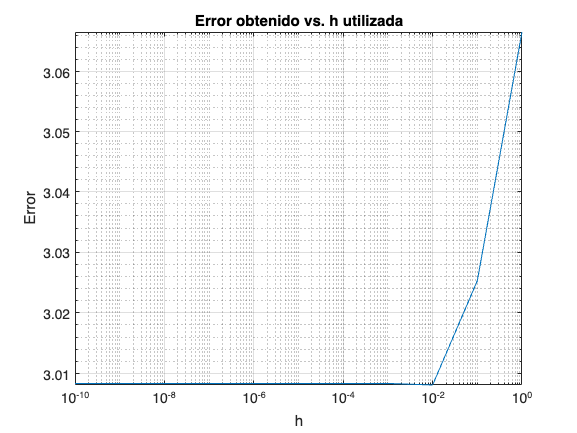

ddfForward1(f,x)

#### Aproximación de la segunda derivada hacia adelante (análogamente hacia atrás) con $O\left(h^2 \right)$

Segunda derivada: Aproximación hacia adelante O(h^2)
	 h 	     aproximación 	 	 error
  1.0000000000 	 0.14431914508912 	  3.1527094331564
  0.1000000000 	 0.17934646030603 	  3.1877367483733
  0.0100000000 	 -3.05275961075505 	  0.0443693226877
  0.0010000000 	 -3.00889804161902 	  0.0005077535517
  0.0001000000 	 -3.00839546607534 	  0.0000051780080
  0.0000100000 	 -3.00839179956380 	  0.0000015114965
  0.0000010000 	 -3.00823949084261 	  0.0001507972247
  0.0000001000 	 -2.98858160441284 	  0.0198086836545
  0.0000000100 	 -1.04083408558608 	  1.9675562024812
  0.0000000010 	 -13.87778780781445 	 10.8693975197471
  0.0000000001 	 693.88939039072272 	 696.8977806787900


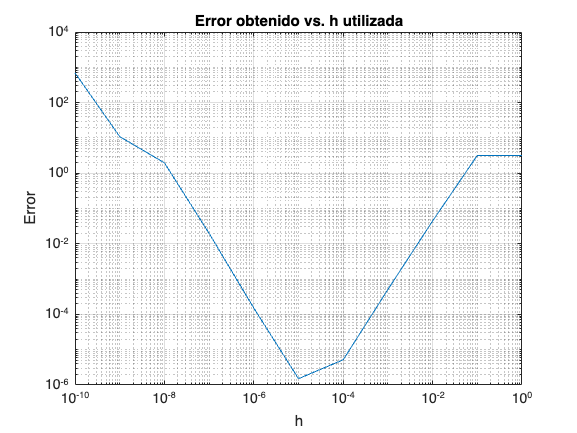

ddfForward2(f,x)

#### Aproximación de la segunda derivada centrada con $O\left(h^2 \right)$

ddfCentral(f,x)

Segunda derivada: Aproximación centrada O(h^2)
	 h 	     aproximación 	 	 error
  1.0000000000 	 -0.02483863190829 	  2.9835516561590
  0.1000000000 	 -2.57001947758157 	  0.4383708104857
  0.0100000000 	 -3.00371880277903 	  0.0046714852883
  0.0010000000 	 -3.00834354353616 	  0.0000467445312
  0.0001000000 	 -3.00838982336682 	  0.0000004647005
  0.0000100000 	 -3.00839183425827 	  0.0000015461910
  0.0000010000 	 -3.00844418821278 	  0.0000539001455
  0.0000001000 	 -3.01043912021015 	  0.0020488321428
  0.0000000100 	 -3.98986399474666 	  0.9814737066793
  0.0000000010 	 -3.46944695195361 	  0.4610566638863
  0.0000000001 	 -346.94469519536136 	 343.9363049072941


**Gráfica con los errores de los métodos para comparar**

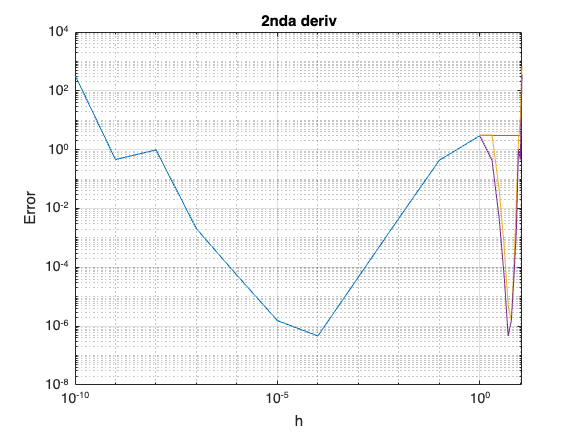

grafTodas2nda(f, x)

### Aproximaciones de la función con derivadas constantes $f\left(x\right)=5x+6$ con `x = 1.00`

f = @(x) 5 * x + 6;
x = 1.00;

#### Primera derivada

En este caso, la primera derivada de la función es una constante:

df = matlabFunction(diff(sym(f)))

df = function_handle with value:
    @()5.0


Aunque los algoritmos sí deben mostrar los resultados de las aproximaciones y sus errores, el programa debe lanzar una advertencia al usuario indicando que las derivadas de la función son constantes.

**Aproximaciones hacia adelante de primer y segundo orden:**

## Resultados de cada uno de los métodos de aproximación de derivación numérica

#### Aproximación de la primera derivada hacia adelante con $O\left(h\right)$

Primera derivada: Aproximación hacia adelante O(h)
	 h 	     aproximación 	 	 error
  1.0000000000 	 5.00000000000000 	  0.0000000000000
  0.1000000000 	 5.00000000000000 	  0.0000000000000
  0.0100000000 	 5.00000000000007 	 -0.0000000000001
  0.0010000000 	 4.99999999999901 	  0.0000000000010
  0.0001000000 	 4.99999999998835 	  0.0000000000117
  0.0000100000 	 4.99999999998835 	  0.0000000000117
  0.0000010000 	 4.99999999981071 	  0.0000000001893
  0.0000001000 	 5.00000000513978 	 -0.0000000051398
  0.0000000100 	 5.00000005843049 	 -0.0000000584305
  0.0000000010 	 5.00000041370185 	 -0.0000004137019
  0.0000000001 	 5.00000041370185 	 -0.0000004137019


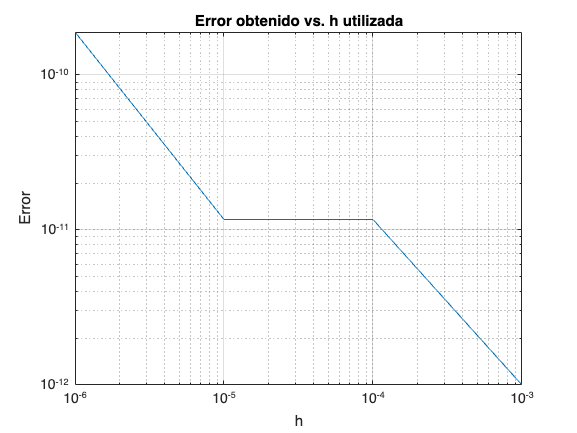

dfForward1(f,x)

#### Aproximación de la primera derivada hacia adelante con $O\left(h^2 \right)$

Primera derivada: Aproximación hacia adelante O(h^2)
	 h 	     aproximación 	 	 error
  1.0000000000 	 5.00000000000000 	  0.0000000000000
  0.1000000000 	 5.00000000000000 	  0.0000000000000
  0.0100000000 	 5.00000000000007 	 -0.0000000000001
  0.0010000000 	 4.99999999999901 	  0.0000000000010
  0.0001000000 	 4.99999999998835 	  0.0000000000117
  0.0000100000 	 5.00000000016598 	 -0.0000000001660
  0.0000010000 	 5.00000000158707 	 -0.0000000015871
  0.0000001000 	 5.00000002290335 	 -0.0000000229034
  0.0000000100 	 5.00000005843049 	 -0.0000000584305
  0.0000000010 	 5.00000041370185 	 -0.0000004137019
  0.0000000001 	 5.00001817727025 	 -0.0000181772702


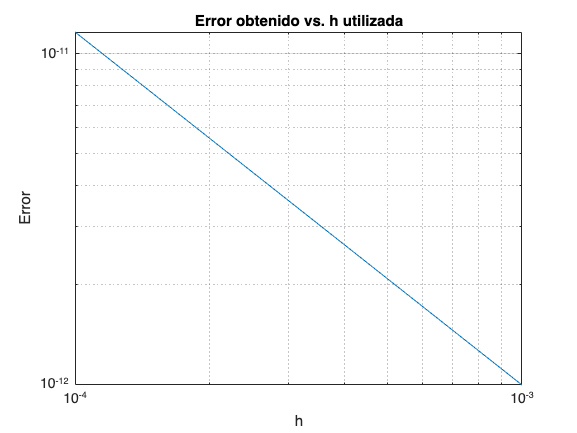

dfForward2(f,x)

#### Aproximación de la primera derivada centrada con $O\left(h^2 \right)$

Primera derivada: Aproximación centrada O(h^2)
	 h 	     aproximación 	 	 error
  1.0000000000 	 5.00000000000000 	  0.0000000000000
  0.1000000000 	 5.00000000000000 	  0.0000000000000
  0.0100000000 	 5.00000000000007 	 -0.0000000000001
  0.0010000000 	 4.99999999999901 	  0.0000000000010
  0.0001000000 	 4.99999999998835 	  0.0000000000117
  0.0000100000 	 4.99999999998835 	  0.0000000000117
  0.0000010000 	 4.99999999981071 	  0.0000000001893
  0.0000001000 	 4.99999999625800 	  0.0000000037420
  0.0000000100 	 5.00000005843049 	 -0.0000000584305
  0.0000000010 	 5.00000041370185 	 -0.0000004137019
  0.0000000001 	 5.00000041370185 	 -0.0000004137019


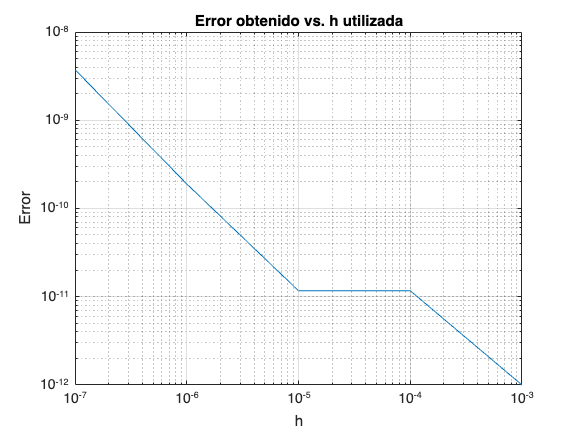

dfCentral(f,x)

#### Aproximación de la primera derivada hacia atrás con $O\left(h\right)$

Primera derivada: Aproximación hacia atrás O(h)
	 h 	     aproximación 	 	 error
  1.0000000000 	 5.00000000000000 	  0.0000000000000
  0.1000000000 	 5.00000000000000 	  0.0000000000000
  0.0100000000 	 5.00000000000007 	 -0.0000000000001
  0.0010000000 	 4.99999999999901 	  0.0000000000010
  0.0001000000 	 4.99999999998835 	  0.0000000000117
  0.0000100000 	 4.99999999998835 	  0.0000000000117
  0.0000010000 	 4.99999999981071 	  0.0000000001893
  0.0000001000 	 4.99999998737621 	  0.0000000126238
  0.0000000100 	 5.00000005843049 	 -0.0000000584305
  0.0000000010 	 5.00000041370185 	 -0.0000004137019
  0.0000000001 	 5.00000041370185 	 -0.0000004137019


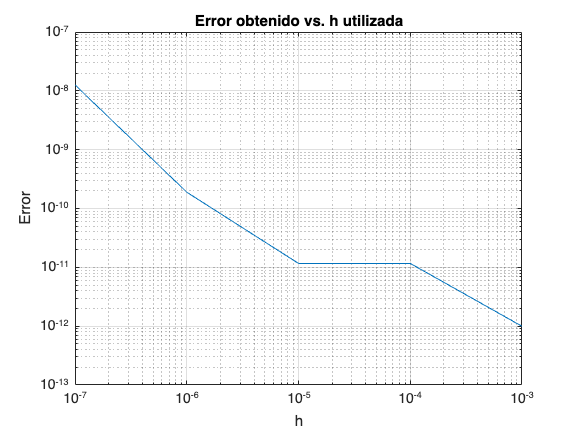

dfBackward1(f,x)

#### Aproximación de la primera derivada hacia atrás con $O\left(h^2 \right)$

dfBackward2(f,x)

Primera derivada: Aproximación hacia atrás O(h^2)
	 h 	     aproximación 	 	 error
  1.0000000000 	 5.00000000000000 	  0.0000000000000
  0.1000000000 	 5.00000000000000 	  0.0000000000000
  0.0100000000 	 5.00000000000016 	 -0.0000000000002
  0.0010000000 	 4.99999999999812 	  0.0000000000019
  0.0001000000 	 4.99999999997947 	  0.0000000000205
  0.0000100000 	 4.99999999998835 	  0.0000000000117
  0.0000010000 	 4.99999999981071 	  0.0000000001893
  0.0000001000 	 4.99999996961265 	  0.0000000303874
  0.0000000100 	 5.00000005843049 	 -0.0000000584305
  0.0000000010 	 5.00000041370185 	 -0.0000004137019
  0.0000000001 	 5.00000041370185 	 -0.0000004137019


**Gráfica con los errores de los métodos para comparar**

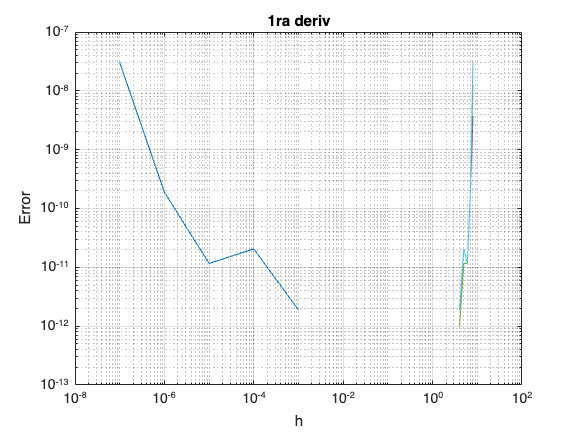

grafTodas1era(f, x)

#### Segunda derivada

Como el resultado de la primera derivada de la función es una constante, la segunda derivada es` 0. Por eso, la gráfica tiene un comportamiento a normal:`

ddf = matlabFunction(diff(diff(sym(f))))

ddf = function_handle with value:
    @()0.0


**Aproximaciones hacia adelante de primer y segundo orden:**

#### Aproximación de la segunda derivada hacia adelante (análogamente hacia atrás) con $O\left(h\right)$

Segunda derivada: Aproximación hacia adelante O(h)
	 h 	     aproximación 	 	 error
  1.0000000000 	 0.00000000000000 	  0.0000000000000
  0.1000000000 	 0.00000000000000 	  0.0000000000000
  0.0100000000 	 -0.00000000000000 	  0.0000000000000
  0.0010000000 	 0.00000000000000 	  0.0000000000000
  0.0001000000 	 0.00000000000000 	  0.0000000000000
  0.0000100000 	 0.00000000000000 	  0.0000000000000
  0.0000010000 	 0.00000000000000 	  0.0000000000000
  0.0000001000 	 -0.00000000000000 	  0.0000000000000
  0.0000000100 	 0.00000000000000 	  0.0000000000000
  0.0000000010 	 0.00000000000000 	  0.0000000000000
  0.0000000001 	 0.00000000000000 	  0.0000000000000


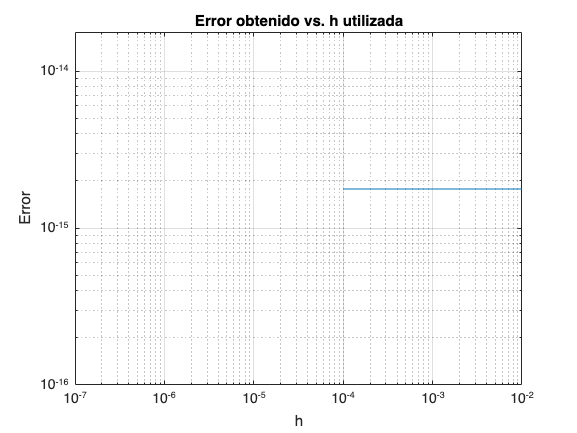

ddfForward1(f,x)

#### Aproximación de la segunda derivada hacia adelante (análogamente hacia atrás) con $O\left(h^2 \right)$

Segunda derivada: Aproximación hacia adelante O(h^2)
	 h 	     aproximación 	 	 error
  1.0000000000 	 0.00000000000000 	  0.0000000000000
  0.1000000000 	 0.00000000000000 	  0.0000000000000
  0.0100000000 	 0.00000000000000 	  0.0000000000000
  0.0010000000 	 0.00000000710543 	  0.0000000071054
  0.0001000000 	 0.00000000000000 	  0.0000000000000
  0.0000100000 	 0.00000000000000 	  0.0000000000000
  0.0000010000 	 0.00000000000000 	  0.0000000000000
  0.0000001000 	 -0.71054273576010 	  0.7105427357601
  0.0000000100 	 71.05427357601000 	 71.0542735760100
  0.0000000010 	 0.00000000000000 	  0.0000000000000
  0.0000000001 	 0.00000000000000 	  0.0000000000000


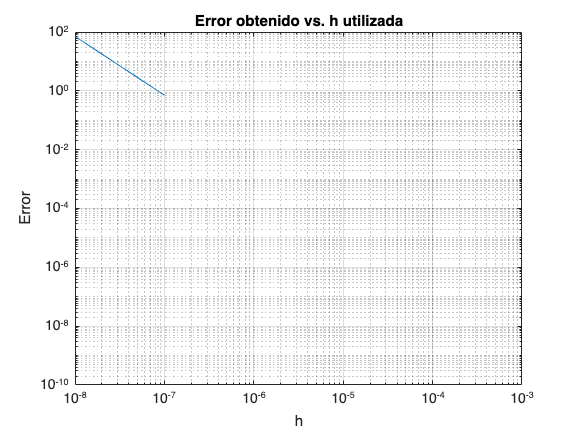

ddfForward2(f,x)

#### Aproximación de la segunda derivada centrada con $O\left(h^2 \right)$

Segunda derivada: Aproximación centrada O(h^2)
	 h 	     aproximación 	 	 error
  1.0000000000 	 0.00000000000000 	  0.0000000000000
  0.1000000000 	 0.00000000000000 	  0.0000000000000
  0.0100000000 	 0.00000000000000 	  0.0000000000000
  0.0010000000 	 0.00000000000000 	  0.0000000000000
  0.0001000000 	 0.00000000000000 	  0.0000000000000
  0.0000100000 	 0.00000000000000 	  0.0000000000000
  0.0000010000 	 0.00000000000000 	  0.0000000000000
  0.0000001000 	 0.17763568394003 	  0.1776356839400
  0.0000000100 	 0.00000000000000 	  0.0000000000000
  0.0000000010 	 0.00000000000000 	  0.0000000000000
  0.0000000001 	 0.00000000000000 	  0.0000000000000


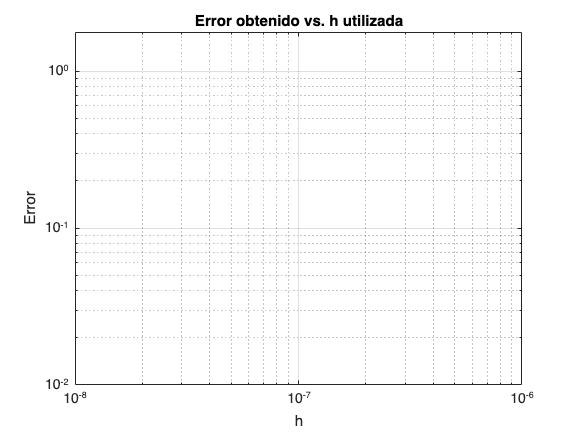

ddfCentral(f,x)

**Gráfica con los errores de los métodos para comparar**

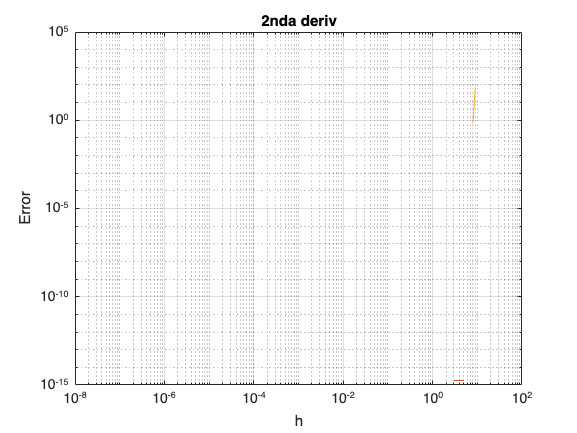

grafTodas2nda(f, x)

### ¿Qué fórmulas presentan menos errores?

El método que reduce al máximo el error, comparado con los otros métodos analizados para la primera derivada, es la fórmula de aproximación hacia atrás con error de truncamiento $O\left(h^2 \right)$ con un error mínimo de $5\ldotp 4{\cdot 10}^{-12}$ y un error máximo de $5\ldotp 4{\cdot 10}^{-12}$. Además, las fórmulas de aproximación centrada con $O\left(h^2 \right)$y hacia adelante con $O\left(h^2 \right)$ presentan el error mínimo que presenta la fórmula anterior, pero tienen errores máximos de una magnitud más grande.

     Por otro lado, la fómula que minimiza el error para la segunda derivada es el método de aproximación centrada con un error de truncamiento $O\left(h\right)$ con un error mínimo de $4\ldotp 6\cdot {10}^{-10}$ y un error máximo de $112\ldotp 7723$. 

    Es interesante recalcar que las aproximaciones centradas tienen un error mínimo menor o igual a los otros métodos para ambas derivadas. 

### ¿Cómo dependen de *h*?

Se encontraron dos comportamientos de las fórmulas cuando estas eran sometidas a diferentes valores de h. En la mayoría de los casos, conforme h era más pequeño, el error se reducía también. Sin embargo, en varios casos, el error se minimizaba cuando $h={10}^{-4}$. Después de ese valor, el error solo aumenta, pero se mantiene menor al error inicial. Esto se puede apreciar en los métodos de la primera derivada. 

    El otro comportamiento consiste en que el error final es mayor al error inicial, aunque, en alguna parte de ese intervalo, se haya alcanzado el error mínimo. Esto lo podemos observar en los métodos de la segunda derivada. 

    Podría decirse que el error de la primera derivada tiene una relación directa respecto h, mientras que el error de la segunda derivada tiene una relación inversa respecto a h.

### ¿El error siempre disminuye si *h* se hace más pequeño?

No. Como se mencionó anteriormente, hay un valor de h que hace que el error sea mínimo. Si se hace más pequeño h, el error solo tiende a aumentar. Para la mayoría de los casos, ese valor fue $h={10}^{-4}$. 

### ¿Qué otro factor influye en el error?

Se debe considerar que igualmente posibles redondeos dentro de la lógica computacional de MatLab generarán una fuente de error sobre las funciones.

### Conclusiones

Estos métodos permiten aproximar la derivada de una función con relativa precisión; sin embargo, existe un margen de error. Siempre será necesario evaluar si el margen es aceptable para lo que se proponga hacer con los resultados, si se trata de un proyecto que requiere de enorme precisión se tendrá que encontrar modos de reducir el error u otros métodos. En la vida profesional ingenieril se utiliza el método de diferencias finitas para problemas físicos de la vida real, dentro de éstos se utiliza frecuentemente para calcular la difusión de calor en cuerpos, como podría ser en el caso de un motor.

### Funciones utilizadas

Funciones auxiliares que nos ayudarán a mostrar los resultados obtenidos y desplegar la gráfica correspondiente en escala log-log.

function muestraResultados(hs, aproxs, err)
% Imprime una tabla de las h generadas, su aproximación, y el error correspondiente.
% Parámetros: h = las h utilizadas en las aproximaciones
% aproxs = los resultados de las aproximaciones
%    err = los errores obtenidos
    format long
    res = [hs' aproxs' err']';
    fprintf('\t h \t     aproximación \t \t error\n');
    fprintf('%14.10f \t %16.14f \t %16.13f\n', res);
    format short
end


function grafError(hs, err)
% Despliega la gráfica correspondiente a las h generadas y sus errores calculados, utilizando la función loglog de MATLAB.
% Parámetros: h = las h utilizadas en las aproximaciones
%    err = los errores obtenidos
    loglog(hs, err)
    grid on
    title('Error obtenido vs. h utilizada')
    xlabel('h')
    ylabel('Error')
end

function grafTodas1era(f, x)
    hold on
    title('1ra deriv')
    [~, ~, err] = ForwardOrder1(f, x, 1, 11);
    plot(err)
    [~, ~, err] = ForwardOrder2(f, x, 1, 11);
    plot(err)
    [~, ~, err] = DerCentral(f, x, 1, 11);
    plot(err)
    [~, ~, err] = BackwardOrder1(f, x, 1, 11);
    plot(err)
    [~, ~, err] = BackwardOrder2(f, x, 1, 11);
    plot(err)
    hold off
end

function grafTodas2nda(f, x)
    hold on
    title('2nda deriv')
    [~, ~, err] = segForwardOrder1(f, x, 1, 11);
    plot(err)
    [~, ~, err] = segForwardOrder2(f, x, 1, 11);
    plot(err)
    [~, ~, err] = segDerCentral(f, x, 1, 11);
    plot(err)
    hold off
end

### PRIMERA DERIVADA

#### Aproximación hacia adelante

**Primer orden **$O\left(h\right)$

La fórmula para la aproximación hacia adelante de la primera derivada $O\left(h\right)$ es: $f^{\left(1\right)} \left(x\right)=\frac{f\left(x+h\right)-f\left(x\right)}{h}$

s

function [hs, aprx, err] = ForwardOrder1(f, x, h, n)
% Realiza n veces la aproximación hacia adelante O(h) de la primera derivada.
% Parámetros: f = función a derivar
%    x = punto a aproximar
%    h = el valor inicial para h
%    n = el número de veces que se realizará la aproximación (dividiendo el
%    valor de h entre 10 en cada ciclo)
% Regresa: hs = las h utilizadas en las aproximaciones
%    aproxs = los resultados de las aproximaciones
%    err = los errores obtenidos

    if nargin(f) == 0
        error('La función es una constante o no cuenta con argumentos de entrada.')
    end
    
    fx = f(x);
    df = matlabFunction(diff(sym(f)));

    if nargin(df) == 0
        df = @(x) df();
        warning('La primera derivada de la función es una constante.')
    end

    dfx = df(x);
    i=0:1:n-1;
    hs=h./10.^(i);
    aprx= (f(x + hs) - fx) ./ hs;
    err=dfx-aprx;
end



function dfForward1(f, x)
% Realiza la aproximación hacia adelante O(h) de la primera derivada, con 
% h = [10^0, 10^-10]. Además, imprime una tabla de las h generadas, su aproximación,
% y el error correspondiente. También genera la gráfica del error vs. la h utilizada.
% Parámetros: f = función a derivar
%    x = punto a aproximar

    [hs, aprxs, err] = ForwardOrder1(f, x, 1, 11);
    fprintf('Primera derivada: Aproximación hacia adelante O(h)\n');
    muestraResultados(hs, aprxs, err)
    grafError(hs, err)
end

**Segundo orden **$O\left(h^2 \right)$

La fórmula para la aproximación hacia adelante de la primera derivada $O\left(h^2 \right)$ es: $f^{\left(1\right)} \left(x\right)=\frac{-\frac{1}{2}f\left(x+2h\right)+2f\left(x+h\right)-\frac{3}{2}f\left(x\right)}{h}=\frac{-f\left(x+2h\right)+4f\left(x+h\right)-3f\left(x\right)}{2h}$

function [hs, aprx, err] = ForwardOrder2(f, x, h, n)
% Realiza n veces la aproximación hacia adelante O(h^2) de la primera derivada.
% Parámetros: f = función a derivar
%    x = punto a aproximar
%    h = el valor inicial para h
%    n = el número de veces que se realizará la aproximación (dividiendo el
%    valor de h entre 10 en cada ciclo)
% Regresa: hs = las h utilizadas en las aproximaciones
%    aprxs = los resultados de las aproximaciones
%    err = los errores obtenidos

    if nargin(f) == 0
        error('La función es una constante o no cuenta con argumentos de entrada.')
    end
    
    fx = f(x);
    df = matlabFunction(diff(sym(f)));

    if nargin(df) == 0
        df = @(x) df();
        warning('La primera derivada de la función es una constante.')
    end
    
    dfx = df(x);
    i=0:1:n-1;
    hs=h./10.^(i);
    aprx = (-f(x + 2 .* hs) + 4 * f(x + hs) - 3 * fx) ./ (2 .* hs);
    err=dfx-aprx;
end


function dfForward2(f, x)
% Realiza la aproximación hacia adelante O(h^2) de la primera derivada, con 
% h = [10^0, 10^-10]. Además, imprime una tabla de las h generadas, su
% aproximación, y el error correspondiente. También genera la gráfica del
% error vs. la h utilizada.
% Parámetros: f = función a derivar
%    x = punto a aproximar

    [hs, aprxs, err] = ForwardOrder2(f, x, 1, 11);
    fprintf('Primera derivada: Aproximación hacia adelante O(h^2)\n');
    muestraResultados(hs, aprxs, err)
    grafError(hs, err)
end

#### Aproximación centrada $O\left(h^2 \right)$

La fórmula para la aproximación centrada de la primera derivada $O\left(h^2 \right)$ es: $f^{\left(1\right)} \left(x\right)=\frac{\frac{1}{2}f\left(x+h\right)-\frac{1}{2}f\left(x-h\right)}{h}=\frac{f\left(x+h\right)-f\left(x-h\right)}{2h}$

function [hs, aprx, err] = DerCentral(f, x, h, n)
% Realiza n veces la aproximación centrada O(h^2) de la primera derivada.
% Parámetros: f = función a derivar
%    x = punto a aproximar
%    h = el valor inicial para h
%    n = el número de veces que se realizará la aproximación (dividiendo el
%    valor de h entre 10 en cada ciclo)
% Regresa: hs = las h utilizadas en las aproximaciones
%    aprxs = los resultados de las aproximaciones
%    err = los errores obtenidos

    if nargin(f) == 0
        error('La función es una constante o no cuenta con argumentos de entrada.')
    end
    
    df = matlabFunction(diff(sym(f)));

    if nargin(df) == 0
        df = @(x) df();
        warning('La primera derivada de la función es una constante.')
    end
    
    dfx = df(x);
    i=0:1:n-1;
    hs=h./10.^(i);
    aprx = (f(x + hs) - f(x - hs)) ./ (2 .* hs);
    err=dfx-aprx;
end


function dfCentral(f, x)
% Realiza la aproximación centrada O(h^2) de la primera derivada, con 
% h = [10^0, 10^-10]. Además, imprime una tabla de las h generadas, su
% aproximación, y el error correspondiente. También genera la gráfica del
% error vs. la h utilizada.
% Parámetros:
%    f = función a derivar
%    x = punto a aproximar

    [hs, aprxs, err] = DerCentral(f, x, 1, 11);
    fprintf('Primera derivada: Aproximación centrada O(h^2)\n');
    muestraResultados(hs, aprxs, err)
    grafError(hs, err)
end


#### Aproximación hacia atrás

**Primer orden **$O\left(h\right)$

La fórmula para la aproximación hacia atrás de la primera derivada $O\left(h\right)$ es: $f^{\left(1\right)} \left(x\right)=\frac{f\left(x\right)-f\left(x-h\right)}{h}$

function [hs, aprx, err] = BackwardOrder1(f, x, h, n)
% Realiza n veces la aproximación hacia atrás O(h) de la primera derivada.
% Parámetros: f = función a derivar
%    x = punto a aproximar
%    h = el valor inicial para h
%    n = el número de veces que se realizará la aproximación (dividiendo el
%    valor de h entre 10 en cada ciclo)
% Regresa: hs = las h utilizadas en las aproximaciones
%    aprxs = los resultados de las aproximaciones
%    err = los errores obtenidos

    if nargin(f) == 0
        error('La función es una constante o no cuenta con argumentos de entrada.')
    end
    
    fx = f(x);    
    df = matlabFunction(diff(sym(f)));

    if nargin(df) == 0
        df = @(x) df();
        warning('La primera derivada de la función es una constante.')
    end
    
    dfx = df(x);
    i=0:1:n-1;
    hs=h./10.^(i);
    aprx = (fx - f(x - hs)) ./ hs;
    err=dfx-aprx;
end


function dfBackward1(f, x)
% Realiza la aproximación hacia atrás O(h) de la primera derivada, con 
% h = [10^0, 10^-10]. Además, imprime una tabla de las h generadas, su
% aproximación, y el error correspondiente. También genera la gráfica del
% error vs. la h utilizada.
% Parámetros: f = función a derivar
%    x = punto a aproximar

    [hs, aprxs, err] = BackwardOrder1(f, x, 1, 11);
    fprintf('Primera derivada: Aproximación hacia atrás O(h)\n');
    muestraResultados(hs, aprxs, err)
    grafError(hs, err)
end

**Segundo orden **$O\left(h^2 \right)$

La fórmula para la aproximación hacia atrás de la primera derivada $O\left(h^2 \right)$ es: $f^{\left(1\right)} \left(x\right)=\frac{\frac{3}{2}f\left(x\right)-2f\left(x-h\right)+\frac{1}{2}f\left(x-2h\right)}{h}=\frac{3f\left(x\right)-4f\left(x-h\right)+f\left(x-2h\right)}{2h}$

function [hs, aprx, err] = BackwardOrder2(f, x, h, n)
% Realiza n veces la aproximación hacia atrás O(h^2) de la primera
% derivada.
% Parámetros: f = función a derivar
%    x = punto a aproximar
%    h = el valor inicial para h
%    n = el número de veces que se realizará la aproximación (dividiendo el
%    valor de h entre 10 en cada ciclo)
% Regresa: hs = las h utilizadas en las aproximaciones
%    aprxs = los resultados de las aproximaciones
%    err = los errores obtenidos

    if nargin(f) == 0
        error('La función es una constante o no cuenta con argumentos de entrada.')
    end
    
    fx = f(x);    
    df = matlabFunction(diff(sym(f)));

    if nargin(df) == 0
        df = @(x) df();
        warning('La primera derivada de la función es una constante.')
    end
    
    dfx = df(x);
    i=0:1:n-1;
    hs=h./10.^(i);
    aprx = (3 * fx - 4 * f(x - hs) + f(x - 2 * hs)) ./ (2 * hs);
    err=dfx-aprx;
end


function dfBackward2(f, x)
% Realiza la aproximación hacia atrás O(h^2) de la primera derivada, con 
% h = [10^0, 10^-10]. Además, imprime una tabla de las h generadas, su
% aproximación, y el error correspondiente. También genera la gráfica del
% error vs. la h utilizada.
% Parámetros: f = función a derivar
%    x = punto a aproximar

    [hs, aprxs, err] = BackwardOrder2(f, x, 1, 11);
    fprintf('Primera derivada: Aproximación hacia atrás O(h^2)\n');
    muestraResultados(hs, aprxs, err)
    grafError(hs, err)
end

### SEGUNDA DERIVADA

Se observó que las fórmulas para la segunda derivada en primer y segundo orden son IGUALES en los casos: Adelante y Atras, por lo que solo se codificara una vez.

#### Aproximación hacia adelante

**Primer orden **$O\left(h\right)$

La fórmula para la aproximación hacia adelante (y análogamente hacia atrás) de la segunda derivada $O\left(h\right)$ es: $f^{\left(2\right)} \left(x\right)=\frac{f\left(x+2h\right)-2f\left(x+h\right)+f\left(x\right)}{h^2 }$

function [hs, aprx, err] = segForwardOrder1(f, x, h, n)
% Realiza n veces la aproximación hacia adelante O(h) de la segunda
% derivada.
% Parámetros: f = función a derivar
%    x = punto a aproximar
%    h = el valor inicial para h
%    n = el número de veces que se realizará la aproximación (dividiendo el
%    valor de h entre 10 en cada ciclo)
% Regresa: hs = las h utilizadas en las aproximaciones
%    aprxs = los resultados de las aproximaciones
%    err = los errores obtenidos

    if nargin(f) == 0
        error('La función es una constante o no cuenta con argumentos de entrada.')
    end
    
    fx = f(x);    
    ddf = matlabFunction(diff(diff(sym(f))));
    
    if nargin(ddf) == 0
        ddf = @(x) ddf();
        warning('La segunda derivada de la función es una constante.')
    end
    
    ddfx = ddf(x);
    i=0:1:n-1;
    hs=h./10.^(i);
    aprx = (f(x + 2 * hs) - 2 * f(x + hs) + fx) ./ h.^ 2;
    err=abs(ddfx - aprx);
end


function ddfForward1(f, x)
% Realiza la aproximación hacia adelante O(h) de la segunda derivada, con 
% h = [10^0, 10^-10]. Además, imprime una tabla de las h generadas, su
% aproximación, y el error correspondiente. También genera la gráfica del
% error vs. la h utilizada.
% Parámetros:
%    f = función a derivar
%    x = punto a aproximar

    [hs, aprxs, err] = segForwardOrder1(f, x, 1, 11);
    fprintf('Segunda derivada: Aproximación hacia adelante O(h)\n');
    muestraResultados(hs, aprxs, err)
    grafError(hs, err)
end

**Segundo orden **$O\left(h^2 \right)$

La fórmula para la aproximación hacia adelante (y análogamente hacia atrás) de la segunda derivada $O\left(h^2 \right)$ es: $f^{\left(2\right)} \left(x\right)=\frac{-f\left(x+3h\right)+4f\left(x+2h\right)-5f\left(x+h\right)+2f\left(x\right)}{h^2 }$

function [hs, aprx, err] = segForwardOrder2(f, x, h, n)
% Realiza n veces la aproximación hacia adelante O(h^2) de la segunda
% derivada.
% Parámetros: f = función a derivar
%    x = punto a aproximar
%    h = el valor inicial para h
%    n = el número de veces que se realizará la aproximación (dividiendo el
%    valor de h entre 10 en cada ciclo)
% Regresa: hs = las h utilizadas en las aproximaciones
%    aprxs = los resultados de las aproximaciones
%    err = los errores obtenidos

    if nargin(f) == 0
        error('La función es una constante o no cuenta con argumentos de entrada.')
    end
    
    fx = f(x);    
    ddf = matlabFunction(diff(diff(sym(f))));
    
    if nargin(ddf) == 0
        ddf = @(x) ddf();
        warning('La segunda derivada de la función es una constante.')
    end
    
    ddfx = ddf(x);
    i=0:1:n-1;
    hs=h./10.^(i);
    aprx = (-f(x + 3 * hs) + 4 * f(x + 2 * hs) - 5 * f(x + hs) + 2 * fx) ./ hs.^ 2;
    err=abs(ddfx - aprx);
end


function ddfForward2(f, x)
% Realiza la aproximación hacia adelante O(h^2) de la segunda derivada, con 
% h = [10^0, 10^-10]. Además, imprime una tabla de las h generadas, su
% aproximación, y el error correspondiente. También genera la gráfica del
% error vs. la h utilizada.
% Parámetros:
%    f = función a derivar
%    x = punto a aproximar

    [hs, aprxs, err] = segForwardOrder2(f, x, 1, 11);
    fprintf('Segunda derivada: Aproximación hacia adelante O(h^2)\n');
    muestraResultados(hs, aprxs, err)
    grafError(hs, err)
end

#### Aproximación centrada $O\left(h^2 \right)$

La fórmula para la aproximación centrada de la segunda derivada $O\left(h^2 \right)$ es: $f^{\left(2\right)} \left(x\right)=\frac{f\left(x+h\right)-2f\left(x\right)+f\left(x-h\right)}{h^2 }$

function [hs, aprx, err] = segDerCentral(f, x, h, n)
% Realiza n veces la aproximación centrada O(h^2) de la segunda derivada.
% Parámetros: f = función a derivar
%    x = punto a aproximar
%    h = el valor inicial para h
%    n = el número de veces que se realizará la aproximación (dividiendo el
%    valor de h entre 10 en cada ciclo)
% Regresa: hs = las h utilizadas en las aproximaciones
%    aprxs = los resultados de las aproximaciones
%    err = los errores obtenidos

    if nargin(f) == 0
        error('La función es una constante o no cuenta con argumentos de entrada.')
    end
    
    fx = f(x);    
    ddf = matlabFunction(diff(diff(sym(f))));
    
    if nargin(ddf) == 0
        ddf = @(x) ddf();
        warning('La segunda derivada de la función es una constante.')
    end
    
    ddfx = ddf(x);
    i=0:1:n-1;
    hs=h./10.^(i);
    aprx = (f(x + hs) - 2 * fx + f(x - hs)) ./ hs.^ 2;
    err=abs(ddfx - aprx);
end


function ddfCentral(f, x)
% Realiza la aproximación centrada O(h^2) de la segunda derivada, con 
% h = [10^0, 10^-10]. Además, imprime una tabla de las h generadas, su
% aproximación, y el error correspondiente. También genera la gráfica del
% error vs. la h utilizada.
% Parámetros: f = función a derivar
%    x = punto a aproximar

    [hs, aprxs, err] = segDerCentral(f, x, 1, 11);
    fprintf('Segunda derivada: Aproximación centrada O(h^2)\n');
    muestraResultados(hs, aprxs, err)
    grafError(hs, err)
end
